# EGB242 Tutorial 9 Computer Lab

clear all, close all, clc

% Type 'doc tf'

% Set up numerator and denominator as per help file
num = [1, 0, 0];
den = [1, 1000, 1e9];
% Create transfer function
tfunc = tf(num, den);

## Question 1

% Poles and zeros
poles = pole(tfunc);
zeros = zero(tfunc);
% Display to command window
disp(poles), disp(zeros)

% Plot
figure(1), clf, pzmap(tfunc) % pole zero map

## Question 2

figure(2),clf, bode(tfunc) % bode plot

## Question 3

% LTIviewer provides a graphical interface to work with a function 
ltiview(tfunc)
% Change line to red and dashed - 2 ways
% 1 - 
% 2 - Command line


% Save to local disk
% 
% Other options


## Question 4

% Characteristics of impulse response

figure(3), impulse(tfunc)

## Question 5

% Set up new transfer function

tfunc2 = tf([1, 0], [1, 1, -5])

tfunc2 =
 
       s
  -----------
  s^2 + s - 5
 
Continuous-time transfer function.



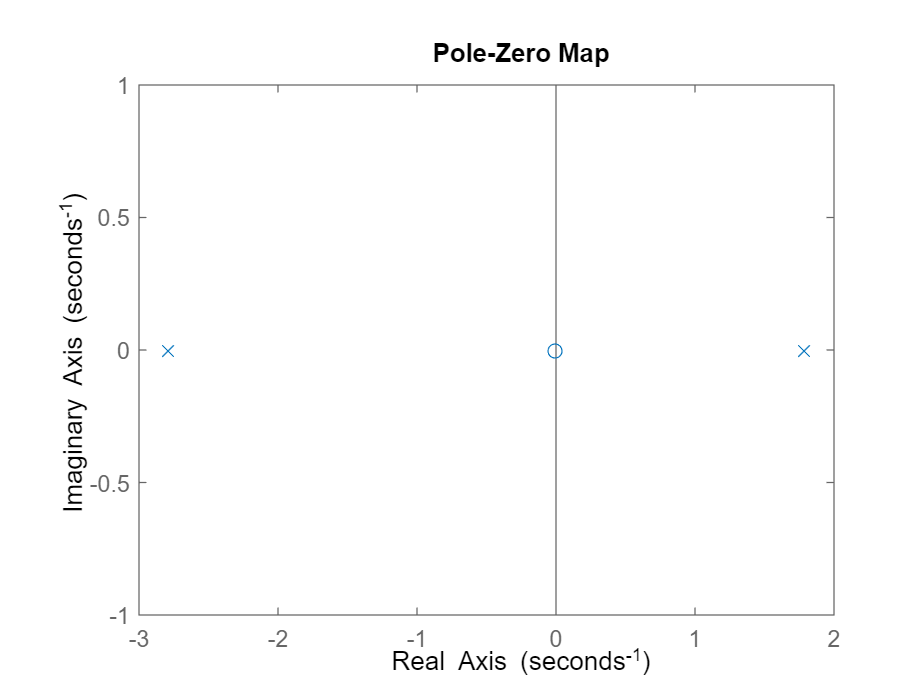

poles = pole(tfunc);
zeros = zero(tfunc);

figure(4), clf, pzmap(tfunc2)